# `Dinámica de una partícula en un potencial de doble pozo`

`Modelado de Sistemas Dinámicos`

`Nombre: Sergio`

`Fecha: 24/04/2026`

## `Resumen`

`En este trabajo se analiza la dinámica de una partícula en un potencial de doble pozo. Se estudian los puntos de equilibrio y su estabilidad, se implementa el modelo en MATLAB y Simulink. Se realizan simulaciones numéricas mediante el método de Runge-Kutta de orden 4.`

## `Introducción`

`El estudio de sistemas dinámicos en potenciales no lineales permite comprender fenómenos físicos complejos. El potencial de doble pozo es un modelo clásico que presenta múltiples puntos de equilibrio y comportamientos oscilatorios.`

`El objetivo de este trabajo es analizar la dinámica del sistema y estudiar su comportamiento bajo distintas condiciones iniciales y parámetros.`

## `Modelo matemático`

#### Potencial


$$V\left(x\right)=a*x^4 -b*x^2$$



$$\frac{\mathrm{dV}}{\mathrm{dx}}=4^* a*x^3 -2*b*x$$


####  Ecuación del movimiento


$$m*x\prime \prime =\frac{\mathrm{dV}}{\mathrm{dx}}$$


####  Sistema de primer orden


$$\begin{array}{l}
x_1 =x\\
x_2 =\frac{\mathrm{dx}}{\mathrm{dt}}\\
x_1 \prime =x_2 \\
x_2 \prime =-\left(\frac{4*a}{m}\right)*x^3 +\left(\frac{2*b}{m}\right)*x
\end{array}$$


#### Puntos de equilibrio y estabilidad


$$x*\left(4*a*x^2 -2*b\right)=0$$


Las soluciones de la ecuacion de grado 3 anterior son:


$$\begin{array}{l}
x=0\\
x=\pm \sqrt{\frac{b}{2*a}}
\end{array}$$


Ahora es necesario evaluar estos puntos en la segunda derivada de la función V(x) para conocer si el punto es un maximo, minimo o punto de silla. En el caso de ser maximo, el punto es inestable, si es un minimo, el punto es estable y en el caso de ser un punto de silla, la estabilidad no es concluyente con solo esta información.


$$\mathrm{V"}\left(x\right)=12*a*x^2 -2*b$$


Por tanto, teniendo en cuenta que los parametros a y b son constantes positivas, se obtiene que:


$$\begin{array}{l}
\mathrm{V"}\left(0\right)=-2b<0\\
V\left(\pm \sqrt{\frac{b}{2*a}}\right)=4b>0
\end{array}$$


Por tanto, se deduce:


$$\begin{array}{l}
x=0\to \mathrm{inestable}\\
x=\pm \sqrt{\frac{b}{2*a}}\to \mathrm{estables}
\end{array}$$


Para poder realizar las simulaciones en Simulink es necesario construir el modelo, es decir, el sistema de ecuaciones de primer orden:


$$\begin{array}{l}
x_1 =x\\
x_2 =x^{\prime } \\
x_1^{\prime } =x_2 \\
x_2^{\prime } =\frac{-4*a}{m}*x_1^3 +\frac{2*b}{m}*x_1 
\end{array}$$


En la herramienta de SimuLink

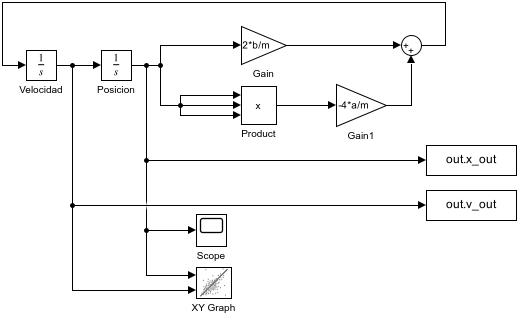

t = x_out.time;
x = x_out.signals.values;
v = v_out.signals.values;

figure
subplot(2,1,1)
plot(t,x,'LineWidth',1.5)
title('Posición vs tiempo')
xlabel('t'); ylabel('x')

subplot(2,1,2)
plot(t,v,'LineWidth',1.5)
title('Velocidad vs tiempo')
xlabel('t'); ylabel('v')